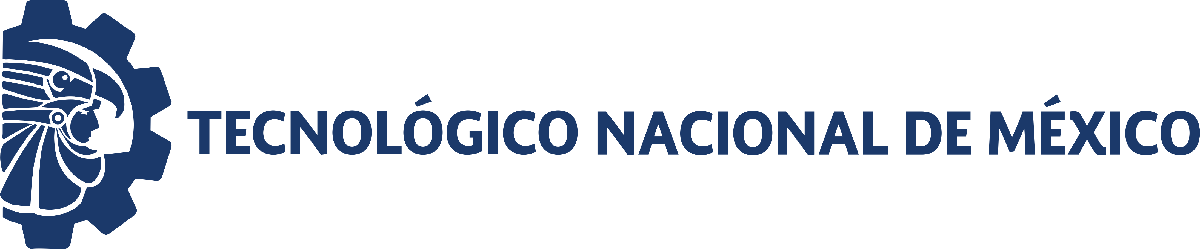                                 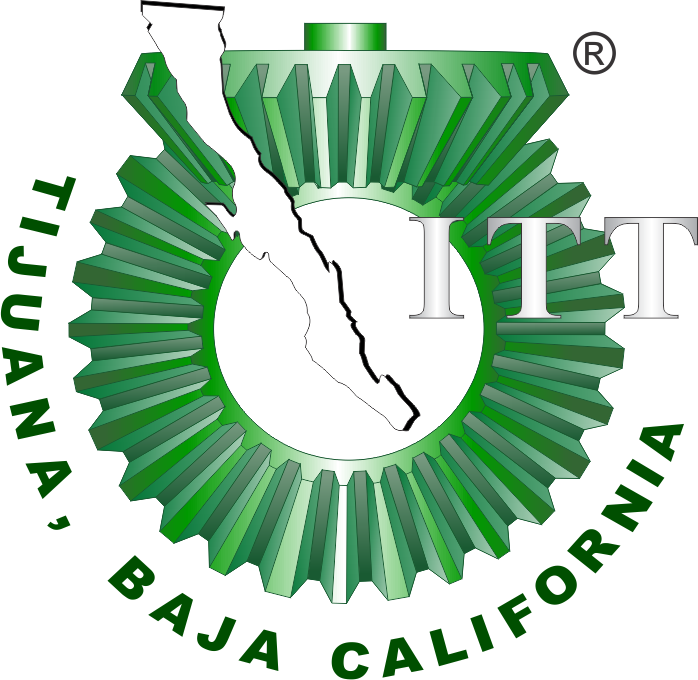

# Práctica cuatro: Sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

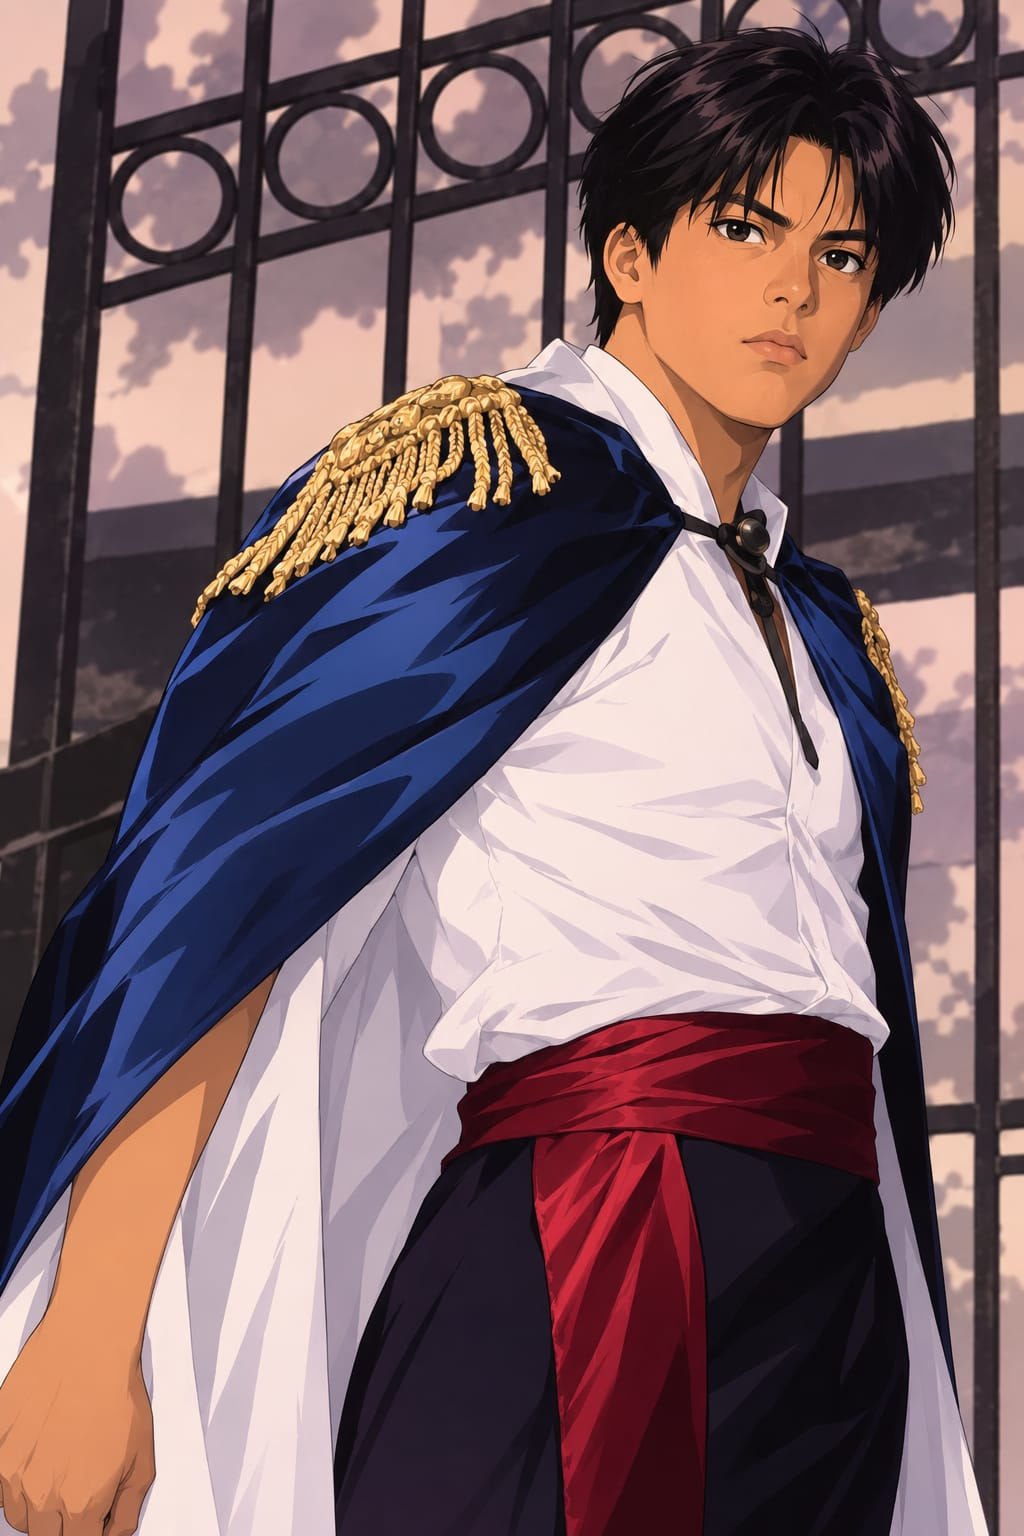

Nombre del alumno: **Emmanuel Cid Pacheco**

Número de control: **23212187**

Correo institucional: **l23212187@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## Respuesta al impulso unitario

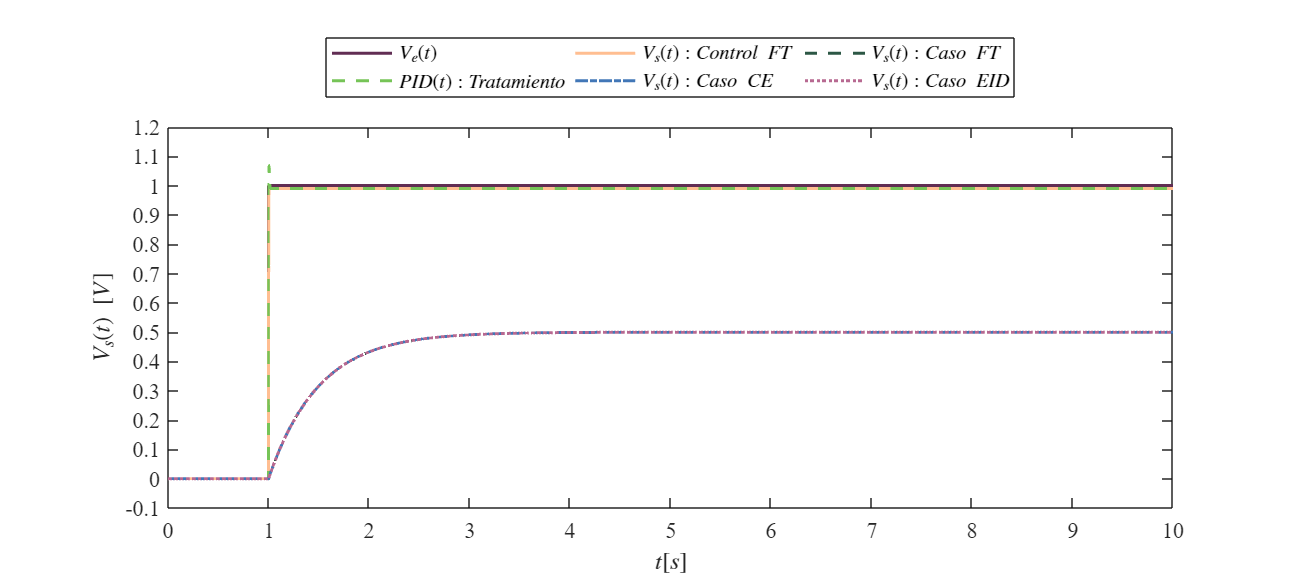

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,x.CE,x.EID)

## Función: Respuesta a las señales

function plotsignals(t,F,Fsx,Fsy,PID,CE,EID)

    t = squeeze(t);
    F = squeeze(F);
    Fsx = squeeze(Fsx);
    Fsy = squeeze(Fsy);
    PID = squeeze(PID);
    CE = squeeze(CE);
    EID = squeeze(EID);

    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,9,4])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1 = [97,45,83]/255;
    clr2 = [255,190,145]/255;
    clr3 = [44,87,69]/255;
    clr4 = [118,196,87]/255;
    clr5 = [66,119,183]/255;
    clr6 = [183,105,145]/255;

    order = [clr1;clr2;clr3;clr4;clr5;clr6];
    colororder(order)

    plot(t,F,'-', ...
         t,Fsx,'-', ...
         t,Fsy,'--', ...
         t,PID,'--', ...
         t,CE,'-.', ...
         t,EID,':', ...
         'LineWidth',1.5);

    L = legend('$V_e(t)$', ...
               '$V_s(t): Control\ FT$', ...
               '$V_s(t): Caso\ FT$', ...
               '$PID(t): Tratamiento$', ...
               '$V_s(t): Caso\ CE$', ...
               '$V_s(t): Caso\ EID$');

    set(L,'interpreter','latex', ...
          'location','northoutside', ...
          'orientation','horizontal', ...
          'NumColumns',3)

    xlabel('$t[s]$','interpreter','latex')
    ylabel('$V_s(t)\ [V]$','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.2]); yticks(-0.1:0.1:1.2)

    exportgraphics(gcf,'Endocrino_matlab.pdf', ...
                   'contenttype','vector')

end